clc; close all; clear;
warning('off','all')
addpath('C:\Users\rdatta\Dropbox (MIT)\PUFFIN\Codes\Other\PlasmaFormulary\')
addpath('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Codes/Other/PlasmaFormulary/')
load physicalConstants-SI.mat c
F = FundamentalPlasma();

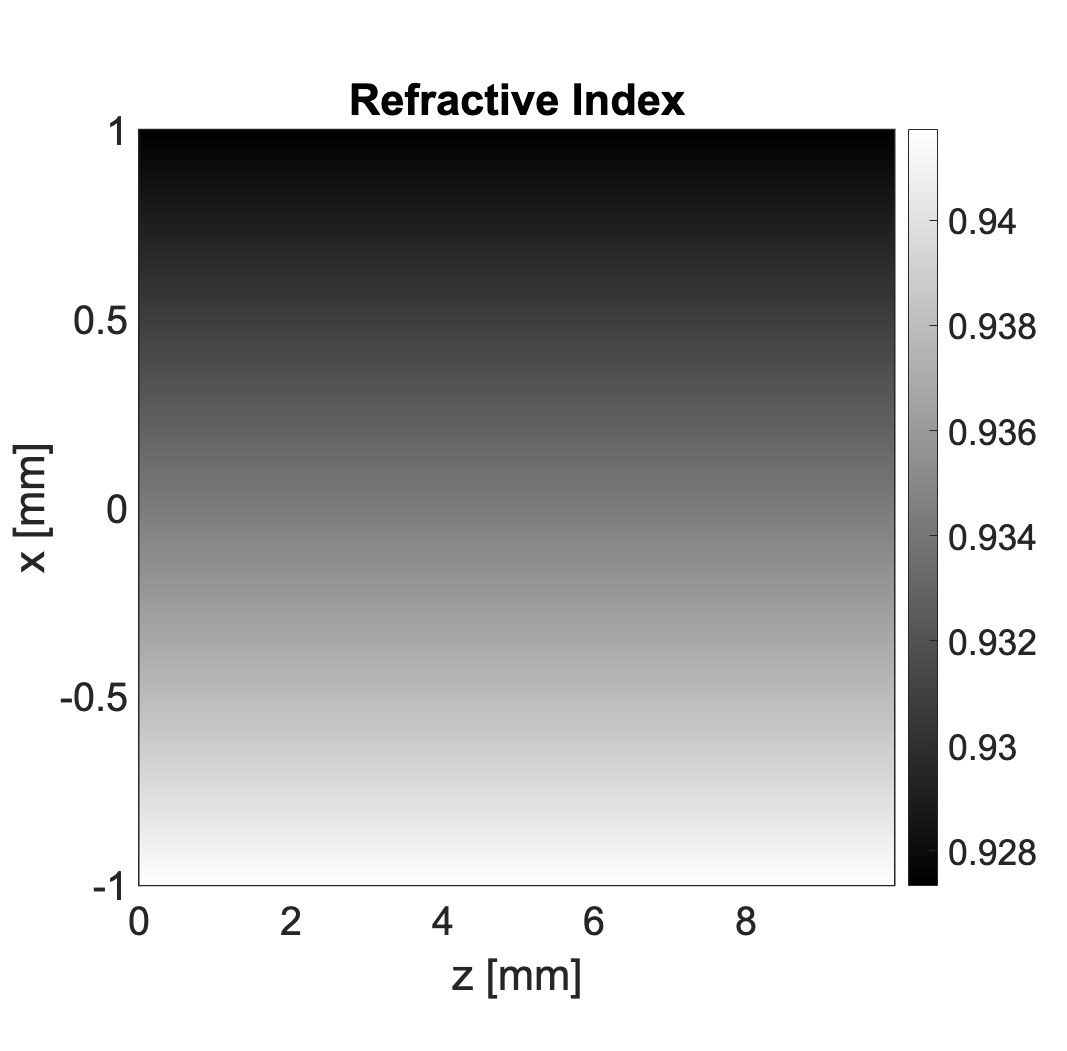

% ID slab

t1 = HamTracer(532e-9,51,[-1e-3,1e-3],[0,10e-3]); % initialize tracer object

% Ref. idx (1D slab)
fname = 'polrizer6';
B = 0.96;
A = B * 4 * 1e-3 / (10e-3)^2; % A = B * 4 * del_x / z^2
N = sqrt(A * t1.xx + B); % refractive idx

load physicalConstants-SI.mat me e 
nc = F.getOwavencrit(t1.lam*100);
al = 0.1; 
ne = al * nc; % constant ne
alp = 1 - al; 
B = me / e * t1.w * alp * sqrt(1-alp./N.^2); % T

N = t1.getXwaveN(ne,B);

t1 = t1.setN(N);

% Solve
xi = linspace(-0.5e-3,0.5e-3,10);
zi = 0 * ones(size(xi));
thi = 0 * ones(size(xi));

tmax = 40 * 2e-3 / c * 2;
t1 = t1.solve(xi,zi,thi,tmax,tmax/200);

figure


figure
t1.showN()
axis square

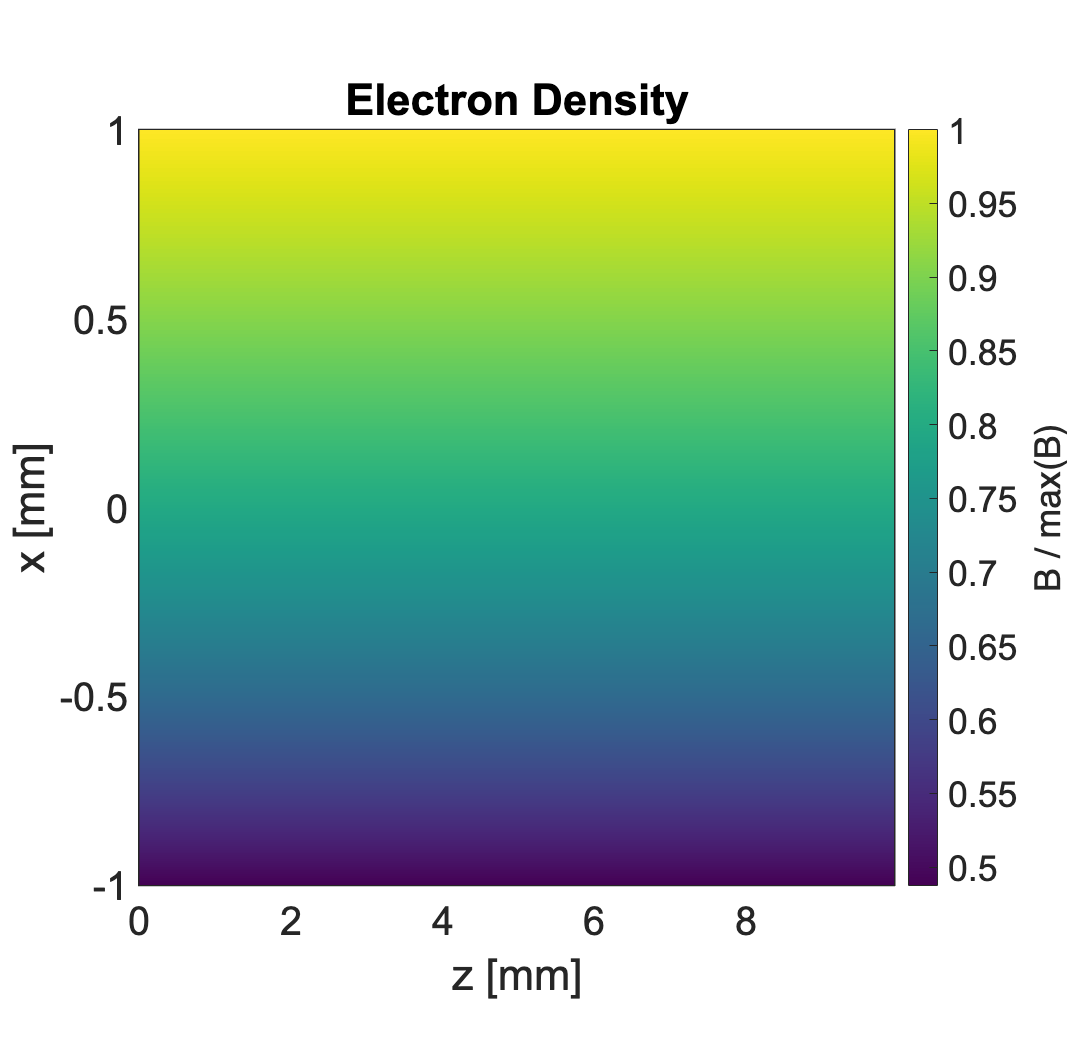


figure
show_B(B,t1)
colormap(viridis());
axis square


figure
hold on;

xend = xi;
zend = 10e-3 * ones(size(xi));
for ii =1:numel(xi)
    plot([zi(ii), zend(ii)]*1e3,[xi(ii),xend(ii)]*1e3,'r',...
        'Linewidth',2);
end

t1.showResults('b')
axis square

hold on;

title(['A = ' num2str(A)])
saveDir = 'Figures/'

saveDir = 'Figures/'

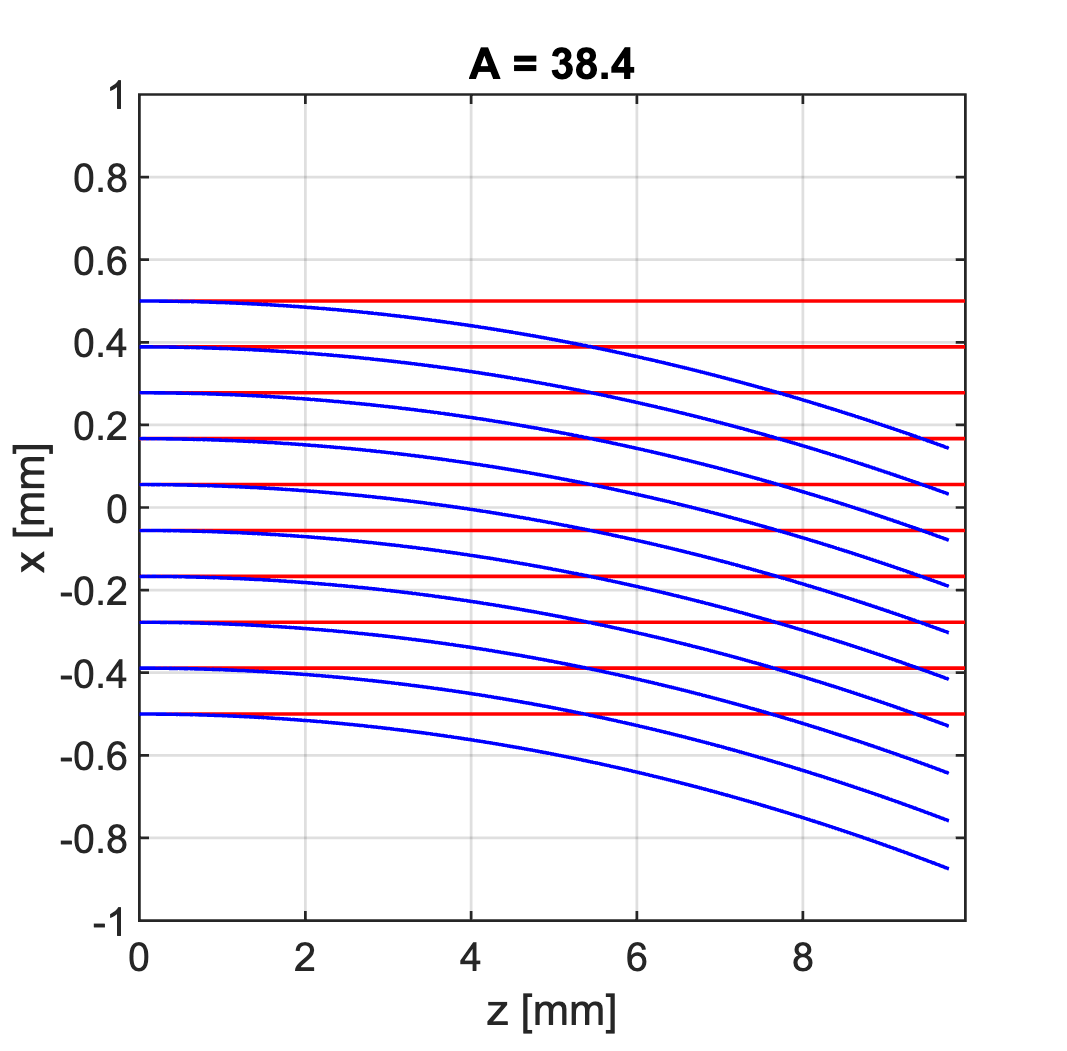

saveas(gcf,[saveDir,fname, '.png'])

function show_B(B,obj)
    surf(obj.zz * 1e3,obj.xx * 1e3,B/max(B(:))); colormap(inferno()); colorbar();
    xlabel('z [mm]');
    ylabel('x [mm]')
    view(2);
    title('Electron Density');
    shading interp
    cb = colorbar();
    ylabel(cb,'B / max(B)')
    formatPlots(600);legend('off');
    axis equal
    ylim(1e3*[min(obj.xx(:)),max(obj.xx(:))])
    xlim(1e3*[min(obj.zz(:)),max(obj.zz(:))])
end
